% PartA

m = linspace(1,9,9);
n = linspace(1,9,5)

n =      1     3     5     7     9



wlo = linspace(0,2000e6,100)

wlo = 1.0e+09 *

         0    0.0202    0.0404    0.0606    0.0808    0.1010    0.1212    0.1414    0.1616    0.1818    0.2020    0.2222    0.2424    0.2626    0.2828    0.3030    0.3232    0.3434    0.3636    0.3838    0.4040    0.4242    0.4444    0.4646    0.4848    0.5051    0.5253    0.5455    0.5657    0.5859    0.6061    0.6263    0.6465    0.6667    0.6869    0.7071    0.7273    0.7475    0.7677    0.7879    0.8081    0.8283    0.8485    0.8687    0.8889    0.9091    0.9293    0.9495    0.9697    0.9899


title_name = 'Spur chart m - 1'

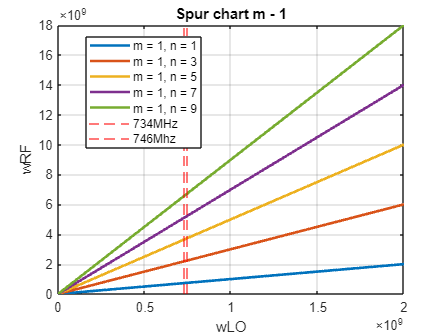

title_name = 'Spur chart m - 2'

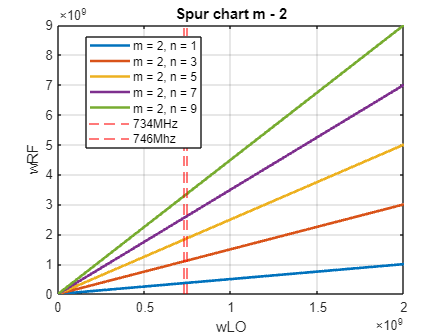

title_name = 'Spur chart m - 3'

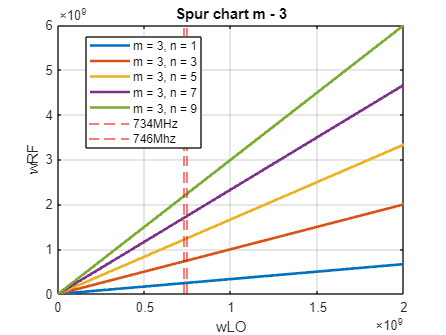

title_name = 'Spur chart m - 4'

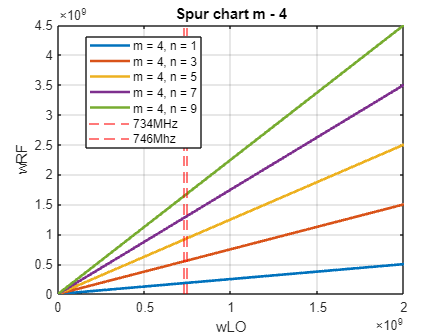

title_name = 'Spur chart m - 5'

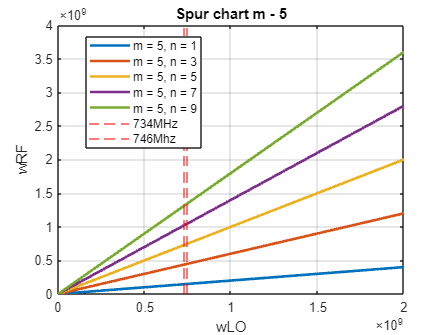

title_name = 'Spur chart m - 6'

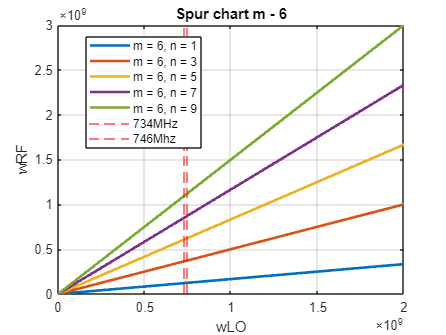

title_name = 'Spur chart m - 7'

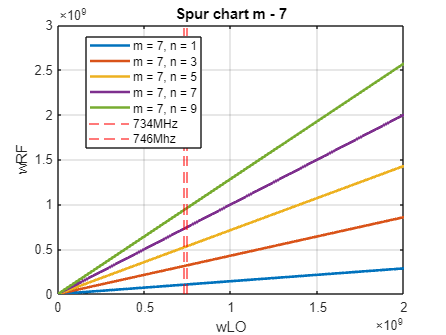

title_name = 'Spur chart m - 8'

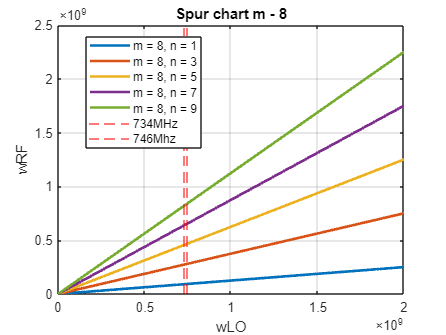

title_name = 'Spur chart m - 9'

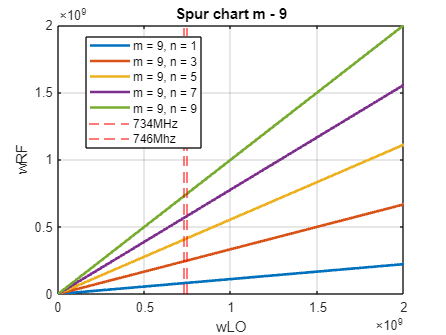

% 
% figure('Position', [400, 400, 800, 400]);  % [left, bottom, width, height]
for j = m
    figure
    for i = n
        wrf = i/j*wlo;
        lable_name = ['m = ',num2str(j),', n = ',num2str(i)];
        plot(wlo,wrf,'LineWidth',2,'DisplayName',lable_name);
        hold on
    end
    xline(734e6, 'r--', 'LineWidth', 0.5,'DisplayName','734MHz');
    xline(746e6, 'r--', 'LineWidth', 0.5,'DisplayName','746Mhz');
    title_name = ['Spur chart',' m - ',num2str(j)]
    title(title_name);
    xlabel('wLO')
    ylabel('wRF')
    
    legend('Location','best')
    
    grid on;
    hold off
    filename = ['Spur chart',' m - ',num2str(j),'.png'];
    saveas(gcf, filename);
end


n = linspace(2,5,4)

n =      2     3     4     5


wlo = linspace(0,2000e6,200)

wlo = 1.0e+09 *

         0    0.0101    0.0201    0.0302    0.0402    0.0503    0.0603    0.0704    0.0804    0.0905    0.1005    0.1106    0.1206    0.1307    0.1407    0.1508    0.1608    0.1709    0.1809    0.1910    0.2010    0.2111    0.2211    0.2312    0.2412    0.2513    0.2613    0.2714    0.2814    0.2915    0.3015    0.3116    0.3216    0.3317    0.3417    0.3518    0.3618    0.3719    0.3819    0.3920    0.4020    0.4121    0.4221    0.4322    0.4422    0.4523    0.4623    0.4724    0.4824    0.4925


for i = n
    wrf = i*wlo;
    lable_name = ['n = ',num2str(i)];
    plot(wlo,wrf,'LineWidth',2,'DisplayName',lable_name);
    hold on
end
yline(1570e6, 'r--', 'LineWidth', 0.25,'DisplayName','1570MHz');
yline(1580e6, 'r--', 'LineWidth', 0.25,'DisplayName','1580Mhz');
title_name = ['Spur chart']

title_name = 'Spur chart'

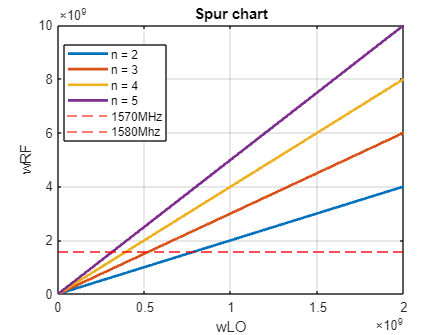

title(title_name);
xlabel('wLO')
ylabel('wRF')

legend('Location','best')
filename = ['Spur chart','.png'];
saveas(gcf, filename);
grid on;
hold off